## Wighted Hinfnorm 

The H-inf norm is tested with the weighting function W_Delta

- Run Test.mlx to obtain the struct param and K

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


%Wdelta = eye(4)*1/(1/0.1*s+1)
Wdelta = eye(4)*tf([1,0],[1,0])

Wdelta =
 
  From input 1 to output...
       s
   1:  -
       s
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
       s
   2:  -
       s
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       s
   3:  -
       s
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
       s
   4:  -
       s
 
Continuous-time transfer function.


WdeltaSS = ss(Wdelta);


Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
Cz = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
Cy = eye(12);

Am = [param.model.A+param.model.B*K*Cy, zeros(12,4);
      WdeltaSS.B*K*Cy, WdeltaSS.A];

Bm = [param.model.B;
      zeros(4,4)]; 

Cm = [WdeltaSS.D*K*Cy, WdeltaSS.C];

Dm = [zeros(4,4)];

M = Cm/(s*eye(16)-Am)*Bm+Dm;


#### Plot Sigma of M equal to $||M||_{ \infty}$ 

plots the four input output relations in1 -> out1, in2 -> out2, in3 ->out3, in4->out4

Use the chekboxes to chose how to save the figure

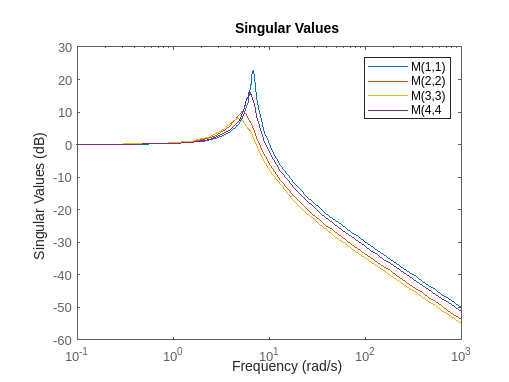

nonWightedPlot = false;
WigthedPlot = false;
sigma(M(1,1),M(2,2),M(3,3),M(4,4))
legend("M(1,1)","M(2,2)","M(3,3)","M(4,4")


if(WigthedPlot)
    saveas(gcf,"Images/SigamMWighted","epsc")
elseif(nonWightedPlot)
    saveas(gcf,"Images/SigamMNonWighted","epsc")

elseif(WigthedPlot && nonWightedPlot)
    saveas(gcf,"Images/SigamMWighted","epsc")
    saveas(gcf,"Images/SigamMNonWighted","epsc")
end
